# Actividad #7

#### Fecha: 22/06/2024

#### Objetivos:

- Opciones adicionales de Live Editor

#### Nombre:

- sunombre

#### Repository:

- [https://github.com/vasanza/SSE](https://github.com/vasanza/SSE)

## Paso 1: Limpiar variables y linea de comandos

clear % Para borrar el workspace y liberar memoria RAM
clc  % Limpiar el command window

## Paso 2: Cargar los datos en formato CSV

Es importante que el archivo csv se encuentre en la misma carpeta que el main

%file=fopen('Data3.csv');
%data=textscan(file,'%d','delimiter','\n');
%fclose(fid);

%Leer un archivo csv y lo carga como una tabla
Dataset=readtable("./data/Data3.csv");
%Convertir la tabla en una matrix de valores
Dataset=table2array(Dataset);
vname=["Corriente","Voltaje","variable3","variable4","variable5"];

## Paso 3: Graficar el dataset

Seleccionar el numero de variables a mostrar

nvar=4;

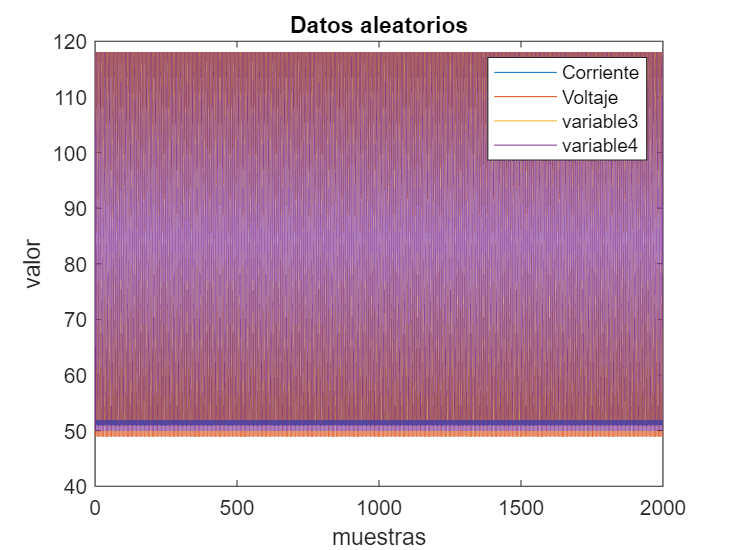

figure %no sobrescribe la anterior grafica
plot(Dataset(:,1:nvar));%
title("Datos aleatorios");
xlabel("muestras");
ylabel("valor");
legend(vname(1:nvar))